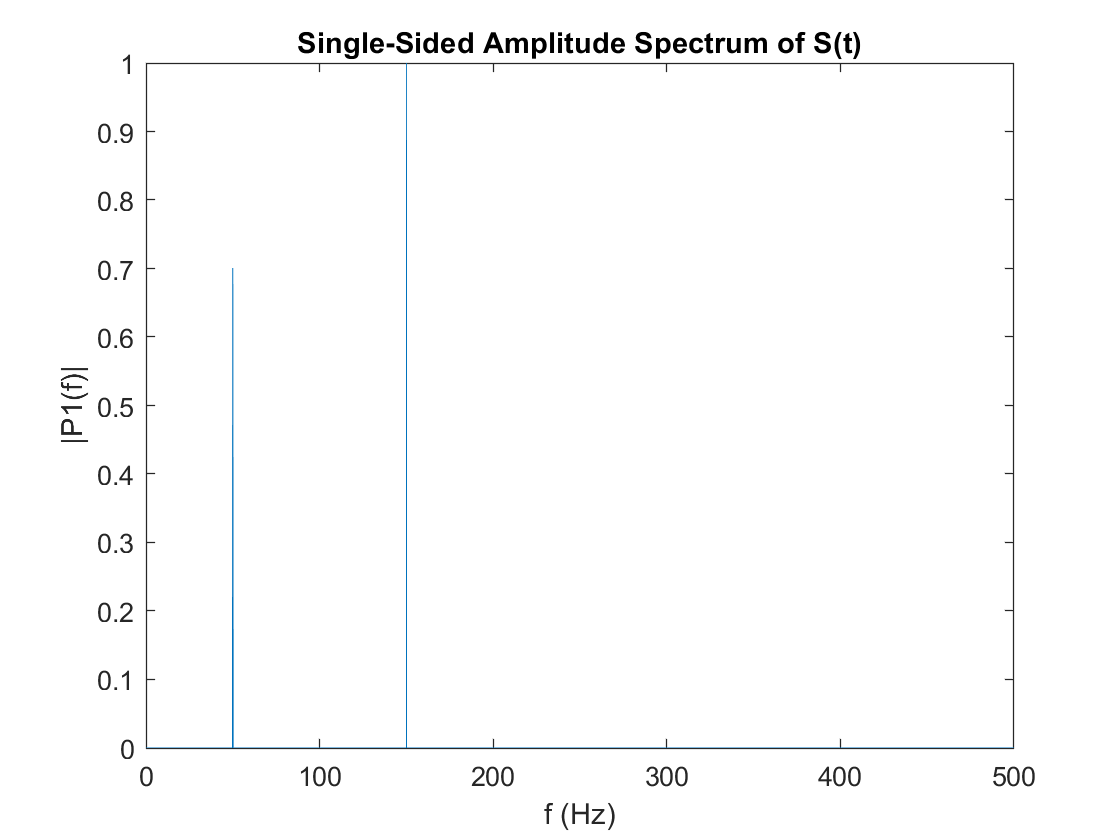

clear;clc
Fs = 1000;            % 采样频率
T = 1/Fs;             % 采样周期
L = 1000;             % 信号长度   由此知，频率分辨率为 1hz
t = (0:L-1)*T;        % 时间相量
S = 0.7*sin(2*pi*50*t+pi/4) + sin(2*pi*150*t-pi/2);   % 原始函数
Y = dft(S);

P2 = abs(Y/L);  % 每个量除以数列长度 L
P1 = P2(1:L/2+1);  % 取交流部分
P1(2:end-1) = 2*P1(2:end-1); % 交流部分模值乘以2
f = Fs*(0:(L/2))/L;
plot(f,P1)
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


f1=Y(1:L/2+1);
f1=atan2(imag(f1),real(f1))+pi/2;
%需要将fft的结果加上pi/2才是真实的值，实验出来的，原理未明。(因为默认公式是cos)
theta = [f1(51) f1(151)]

theta =     0.7854    4.7124


function Xk = dft(x)
    [N,M] = size(x);
    if M~=1
        x = x';
        N = M;
    end
    Xk = zeros(N,1);
    n = 0:N-1;
    for k = 0:N-1
        Xk(k+1) = exp(-j*2*pi*k*n/N)*x;
    end
end